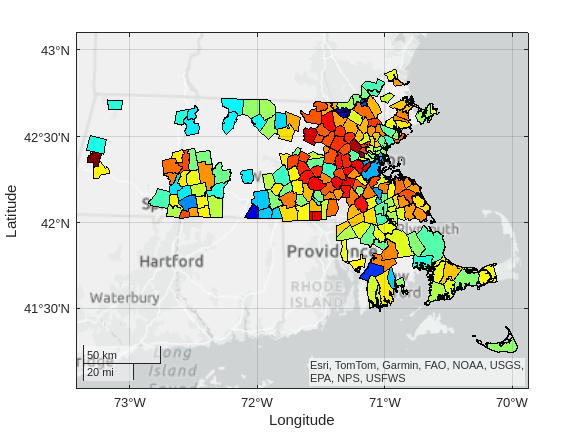

MCASData = readtable("MCAS.csv");
MCASData.MUNI = categorical(upper(MCASData.MUNI));
munis = readgeotable("townssurvey_shp/TOWNSSURVEY_POLY.shp");
munis.MUNI = categorical(munis.TOWN);

meansmunis = innerjoin(munis,MCASData);
geoplot(meansmunis,ColorVariable="AvgScore");
colormap(jet);